# Homework 7: Use Experiment 1 data only

## Loading Data


folderPath = '/Users/giulianabilbao/Desktop/BCI Lab/Lab_8'; 
fileList = dir(fullfile(folderPath, '*.mat'));


loadedData = struct();


for i = 1:length(fileList)
 
    fileName = fileList(i).name;
    filePath = fullfile(folderPath, fileName);
    loadedData.(matlab.lang.makeValidName(fileName)) = load(filePath);
    fprintf('Loaded file: %s\n', fileName);
end

Loaded file: Lab7_group5_p1_attend_both.mat
Loaded file: Lab7_group5_p1_attend_left.mat
Loaded file: Lab7_group5_p1_attend_none.mat
Loaded file: Lab7_group5_p1_attend_right.mat
Loaded file: Lab7_group5_p2_35hz_1031.mat
Loaded file: Lab7_group5_p2_35hz_1107.mat
Loaded file: Lab7_group5_p2_40hz.mat
Loaded file: Lab7_group5_p3.mat



disp('All .mat files loaded successfully.');

All .mat files loaded successfully.


## Question 1: Plot the time waveform of the sounds used in your experiments (only the first 100ms of the signal, separately for the left ear and the right ear) and their time-frequency decomposition called a spectrogram (use specgram function in MATLAB). (1 pt)

- I assume experiment 1 sounds only

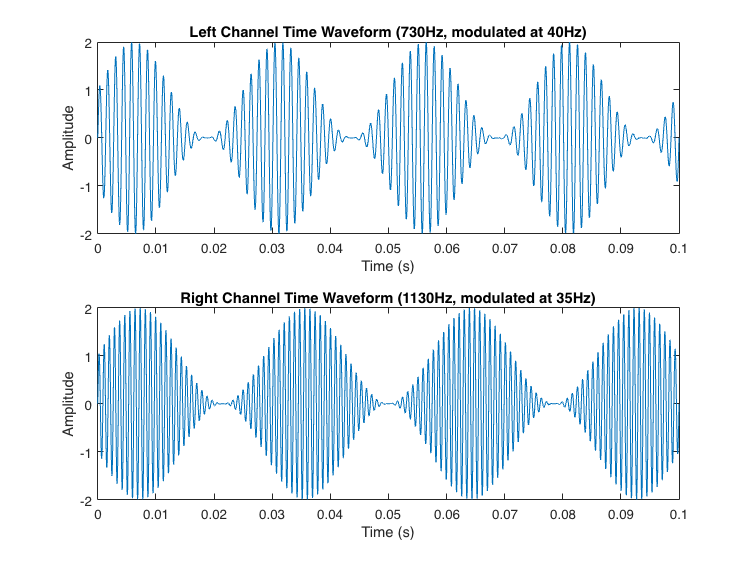


fs = 100000; 
t = 0:1/fs:0.1; 

% Left channel: 730Hz tone modulated at 40Hz
freq_left = 730; 
mod_left = 40;
left_signal = sin(2*pi*freq_left.*t) .* (1 + sin(2*pi*mod_left.*t));

% Right channel: 1130Hz tone modulated at 35Hz
freq_right = 1130; 
mod_right = 35;
right_signal = sin(2*pi*freq_right.*t) .* (1 + sin(2*pi*mod_right.*t));

figure;

% Left channel 
subplot(2, 1, 1);
plot(t, left_signal);
title('Left Channel Time Waveform (730Hz, modulated at 40Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.1]);

% Right channel 
subplot(2, 1, 2);
plot(t, right_signal);
title('Right Channel Time Waveform (1130Hz, modulated at 35Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.1]);

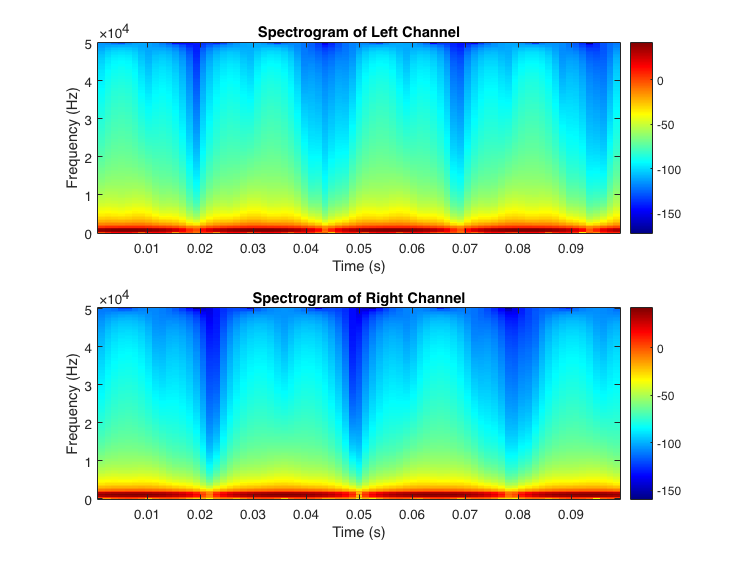


figure;

% Left channel spectrogram
subplot(2, 1, 1);
specgram(left_signal, 256, fs); 
title('Spectrogram of Left Channel');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

% Right channel spectrogram
subplot(2, 1, 2);
specgram(right_signal, 256, fs); 
title('Spectrogram of Right Channel');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

## Question 2: Load the EEG signal in Matlab. Use the trigger signal from the s-function to separate the EEG response to sound. (1 pt)

- Trying from 100 to 300

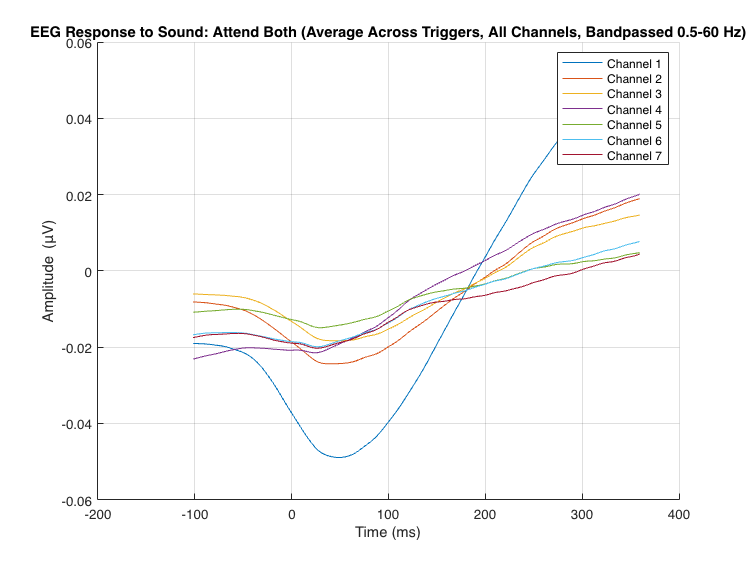

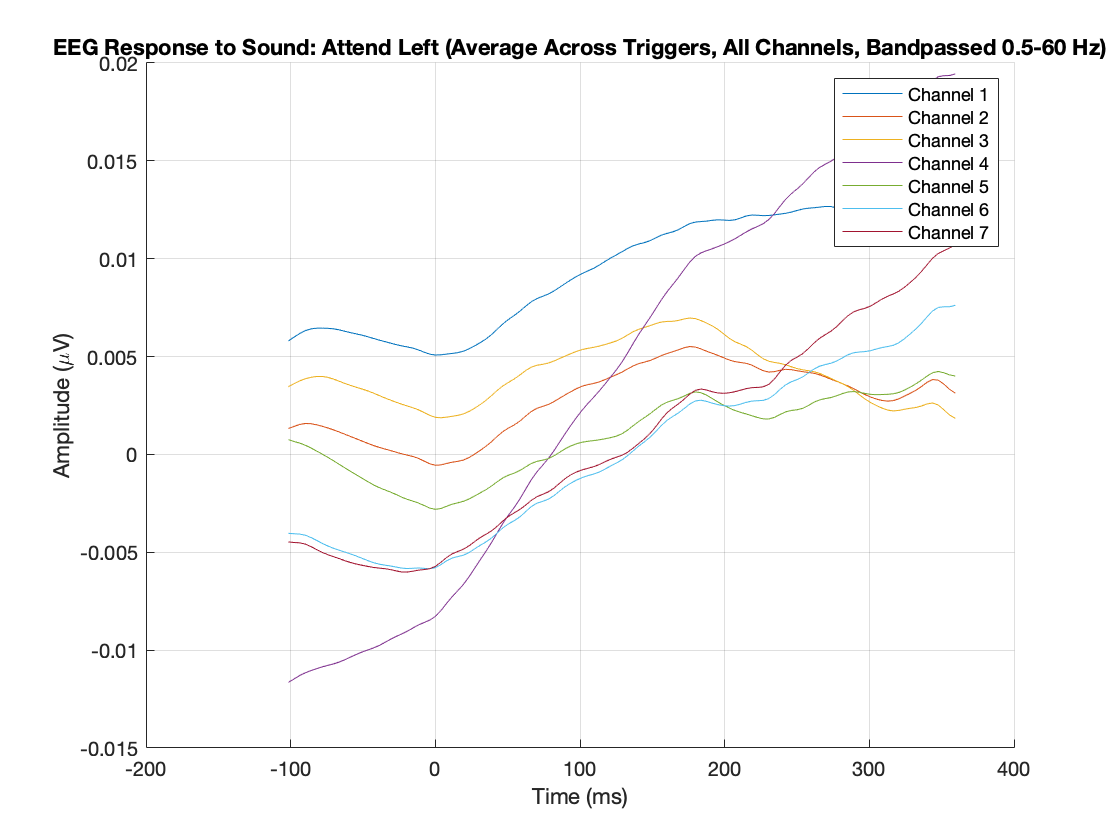

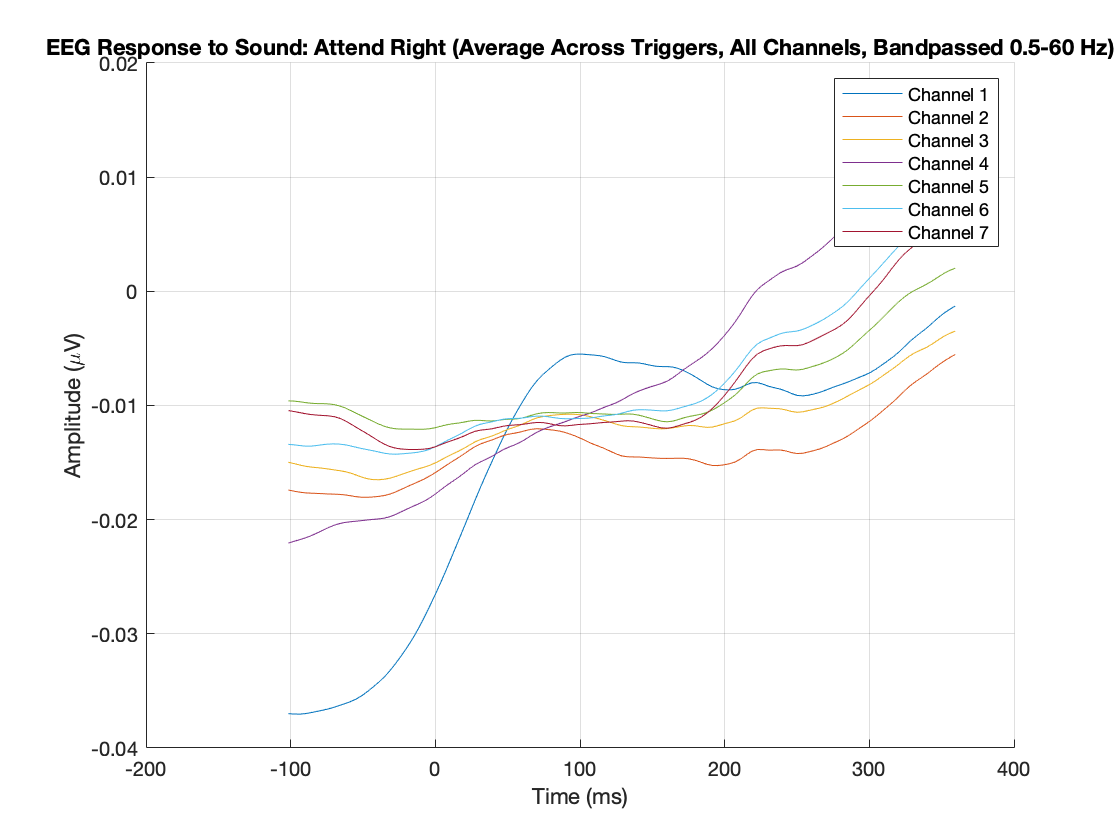

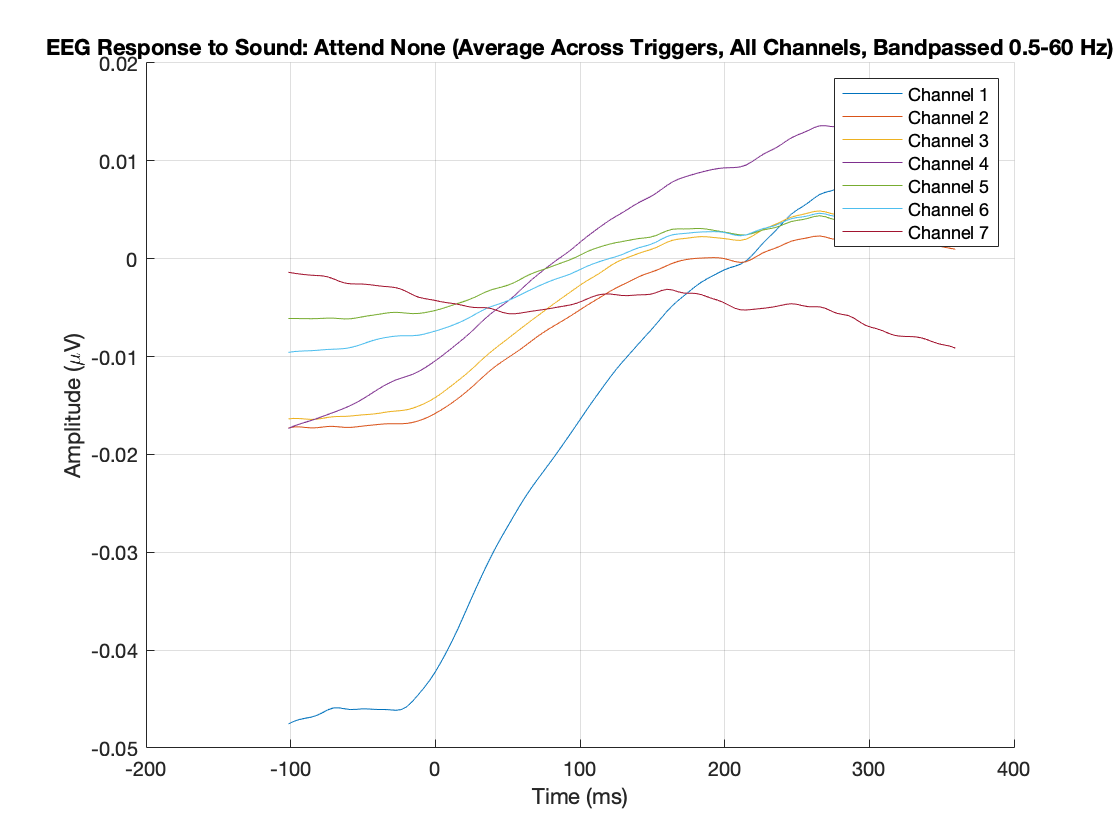


fs = 256; 
pre_time = -100; 
post_time = 360; 
pre_samples = round(pre_time / 1000 * fs); 
post_samples = round(post_time / 1000 * fs); 


bandpass_range = [0.5 60]; % Frequency range for bandpass filter


conditions = {'Lab7_group5_p1_attend_both_mat', 'Lab7_group5_p1_attend_left_mat', ...
              'Lab7_group5_p1_attend_right_mat', 'Lab7_group5_p1_attend_none_mat'};
titles = {'EEG Response to Sound: Attend Both', 'EEG Response to Sound: Attend Left', ...
          'EEG Response to Sound: Attend Right', 'EEG Response to Sound: Attend None'};

for cond_idx = 1:length(conditions)

    data_matrix = loadedData.(conditions{cond_idx}).ans;
    eeg_data = data_matrix(2:8, :);

    %bandpass filter to each channel
    for ch = 1:size(eeg_data, 1)
        eeg_data(ch, :) = bandpass(eeg_data(ch, :), bandpass_range, fs);
    end

    %trigger signal (last row)
    trigger_signal = data_matrix(end, :);

    %trigger indices (where trigger signal fires)
    trigger_indices = find(trigger_signal > 0); % Adjust threshold if needed
    n_triggers = length(trigger_indices);
    n_channels = size(eeg_data, 1);
    segment_length = post_samples - pre_samples + 1;

    eeg_segments = zeros(n_triggers, n_channels, segment_length);

    %EEG segments for each trigger
    for i = 1:n_triggers
        trigger_index = trigger_indices(i);
        segment_start = trigger_index + pre_samples;
        segment_end = trigger_index + post_samples;

%CHECK
        if segment_start > 0 && segment_end <= size(eeg_data, 2)
            eeg_segments(i, :, :) = eeg_data(:, segment_start:segment_end);
        end
    end

    % average response across triggers for each channel
    average_response = squeeze(mean(eeg_segments, 1));
    time_vector = (pre_samples:post_samples) / fs * 1000; 


    figure;
    hold on; 
    for ch = 1:n_channels
        plot(time_vector, average_response(ch, :), 'DisplayName', ['Channel ', num2str(ch)]);
    end
    hold off;

    title([titles{cond_idx}, ' (Average Across Triggers, All Channels, Bandpassed 0.5-60 Hz)']);
    xlabel('Time (ms)');
    ylabel('Amplitude (\muV)');
    legend('show'); 
    grid on;
end

## Question 3: Take the Fourier transform of each channel, and then average the magnitude of FFT over all channels. (1 pt)


fs = 256; 
mod_frequencies = [40, 35]; 
nfft = 1024; % FFT points

freq_vector = (0:(nfft/2 - 1)) * (fs / nfft); 


indices_40Hz = round(40 * nfft / fs);
indices_35Hz = round(35 * nfft / fs);


FFT index for 40 Hz: 160, Corresponding Frequency: 39.75 Hz


FFT index for 35 Hz: 140, Corresponding Frequency: 34.75 Hz


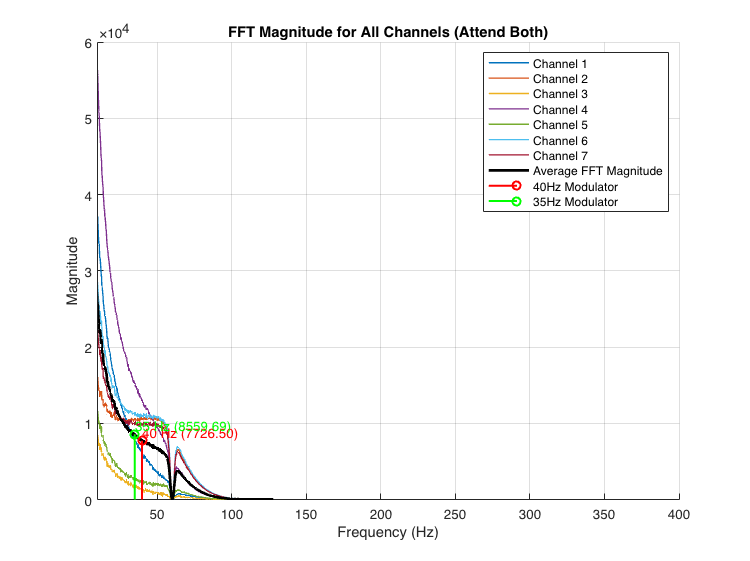

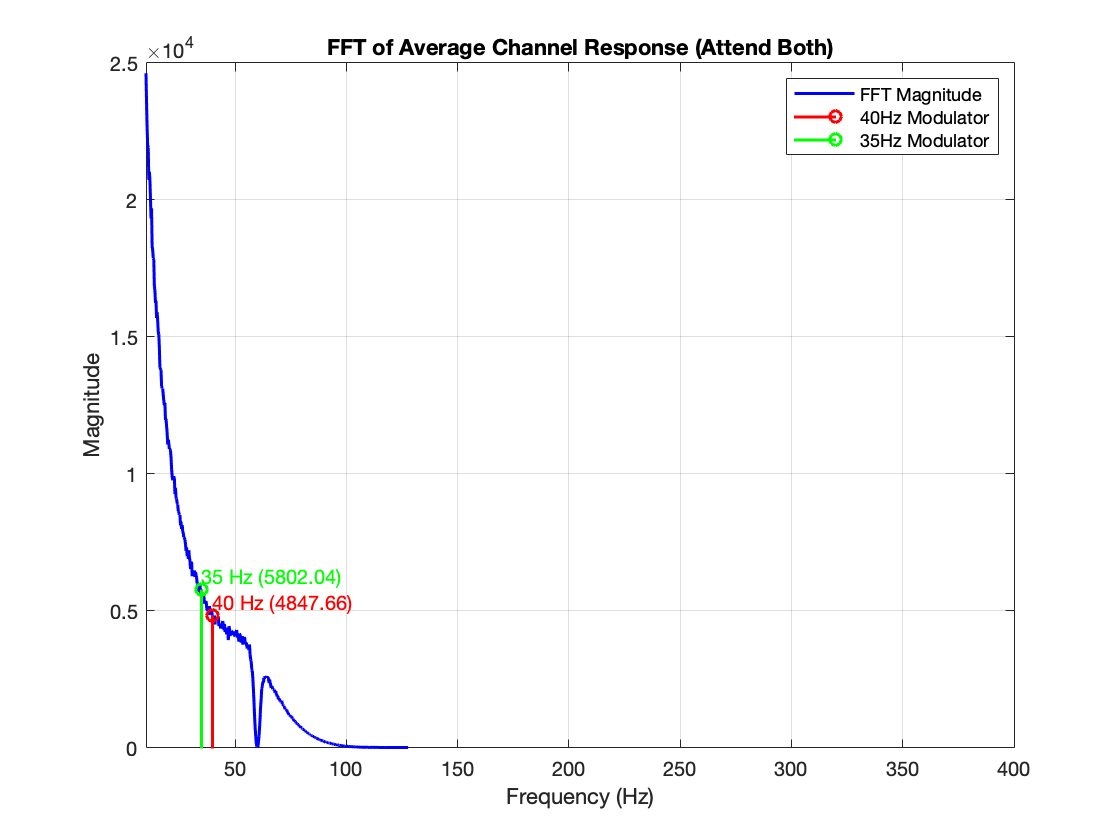

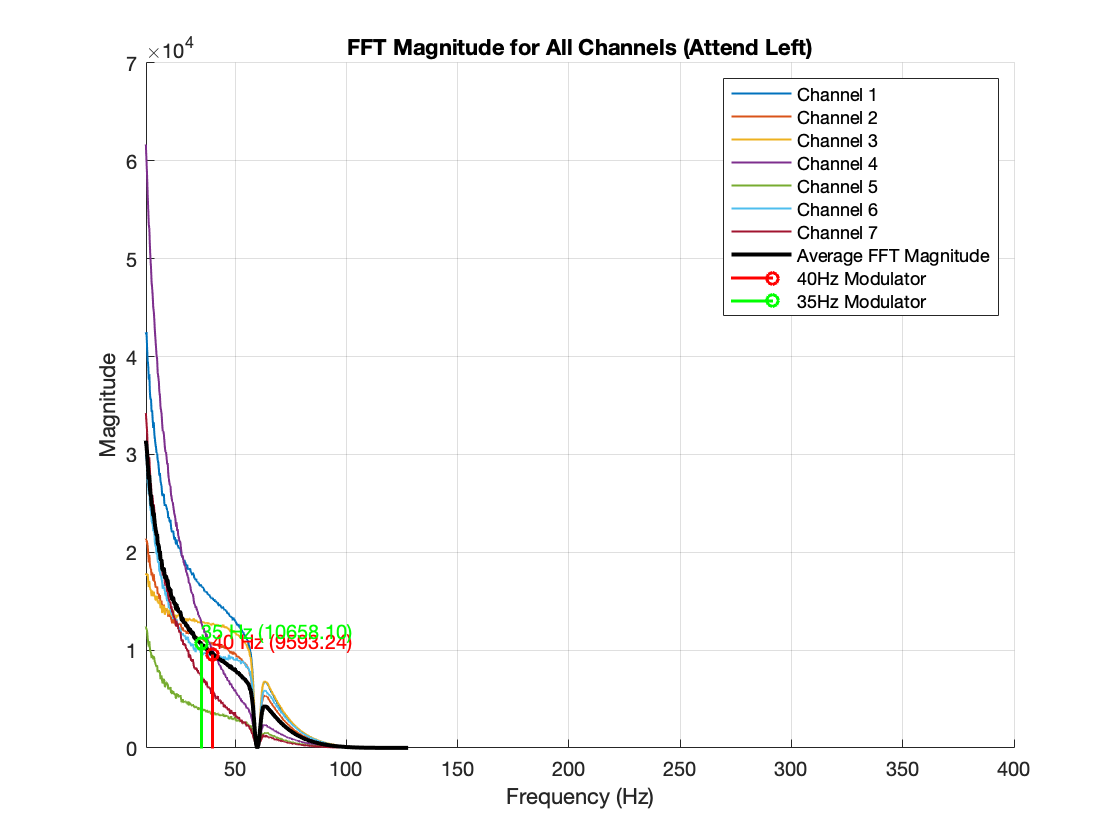

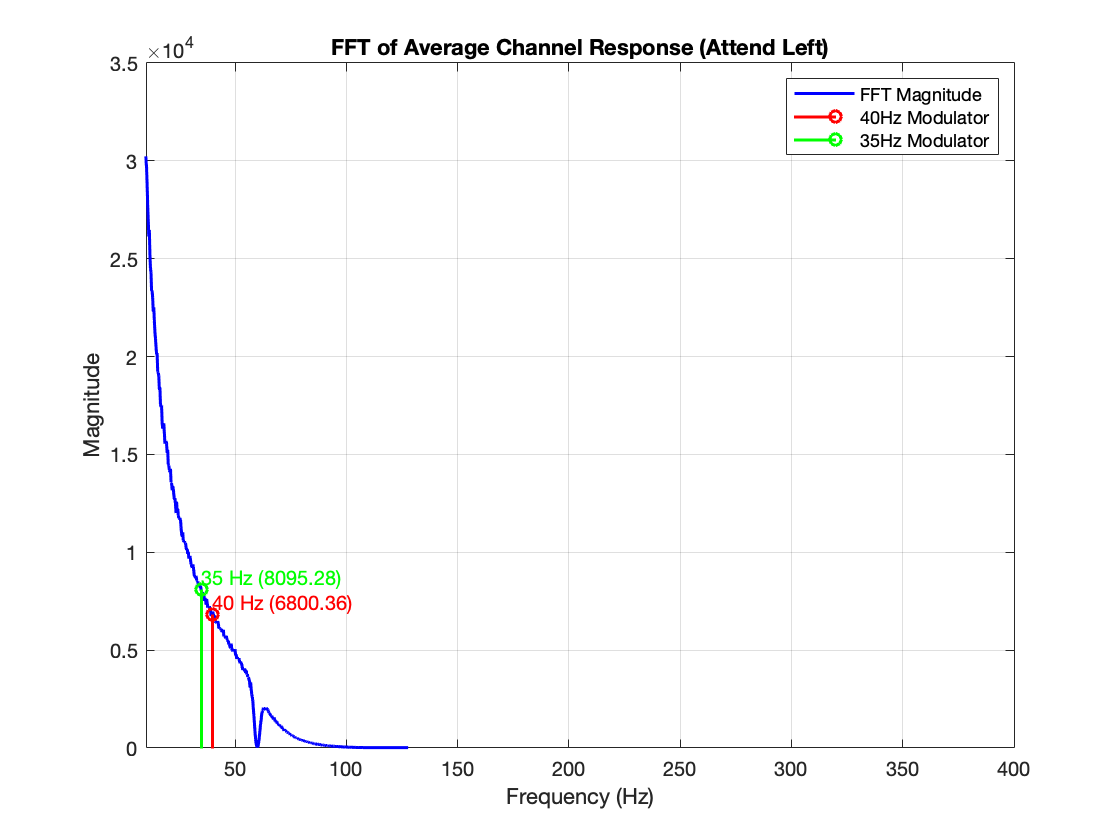

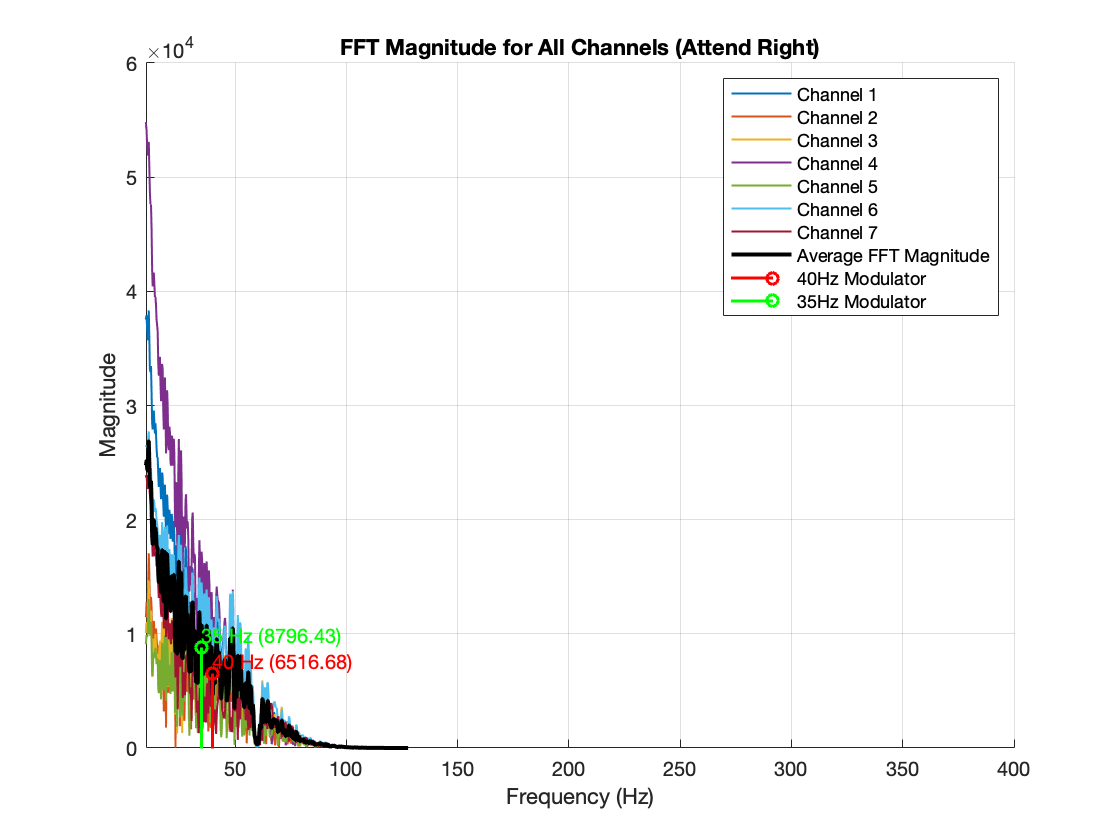

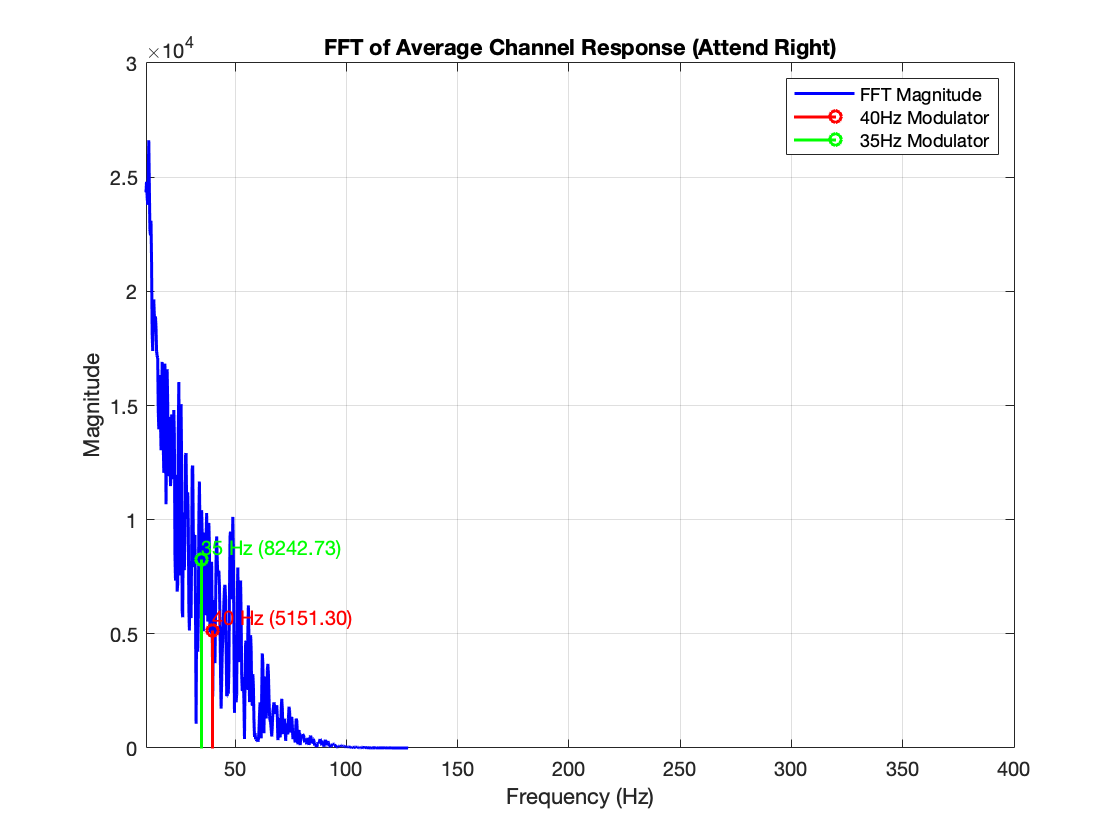

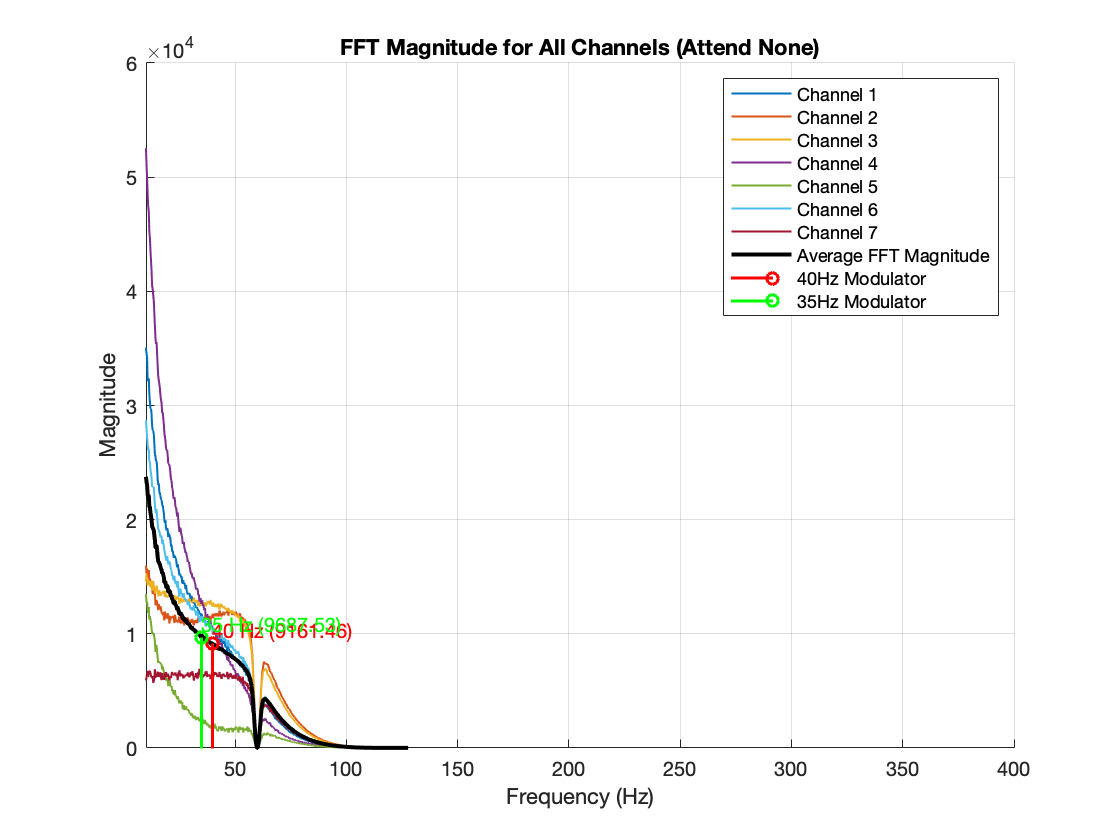

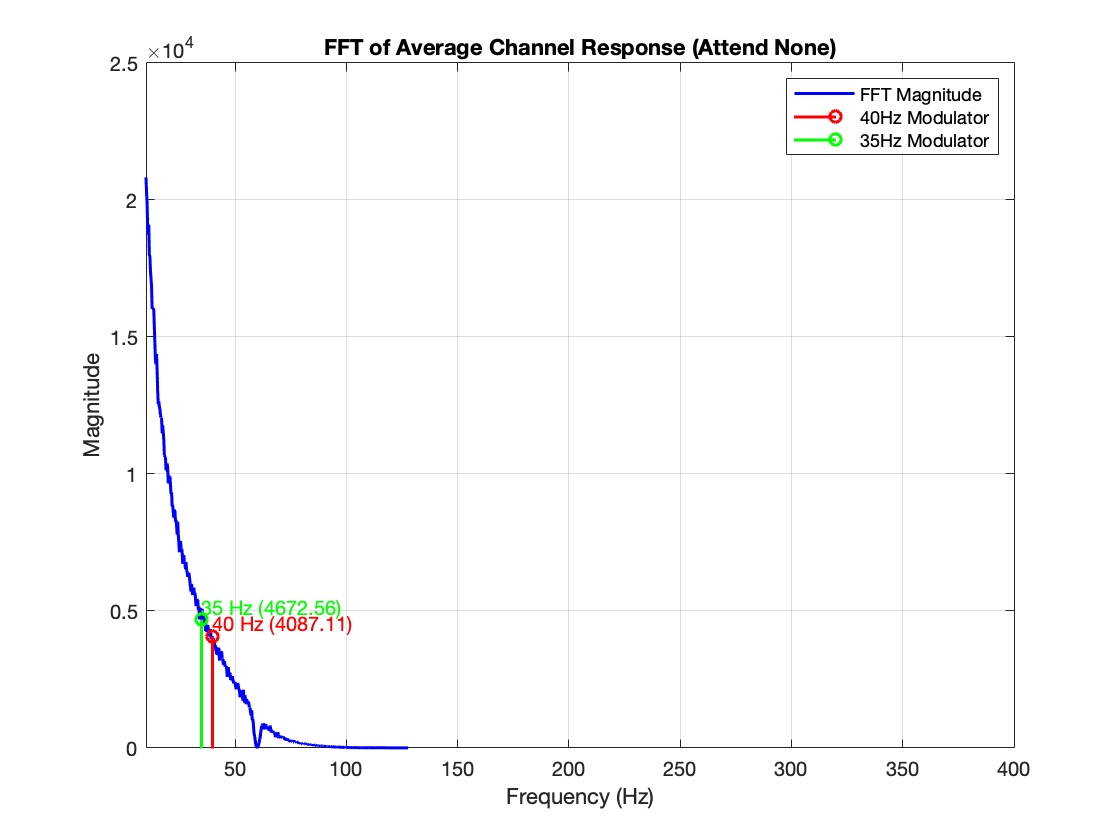

conditions = {'Lab7_group5_p1_attend_both_mat', 'Lab7_group5_p1_attend_left_mat', ...
              'Lab7_group5_p1_attend_right_mat', 'Lab7_group5_p1_attend_none_mat'};
titles = {'Attend Both', 'Attend Left', 'Attend Right', 'Attend None'};

for cond_idx = 1:length(conditions)
    data_matrix = loadedData.(conditions{cond_idx}).ans;
    
    eeg_data = data_matrix(2:8, :);
    n_channels = size(eeg_data, 1);

    %FFT for each channel
    fft_magnitudes = zeros(n_channels, nfft / 2); % Preallocate for FFT magnitudes
    for ch = 1:n_channels
        %only positive frequencies
        fft_result = fft(eeg_data(ch, :), nfft); % Full FFT
        fft_magnitudes(ch, :) = abs(fft_result(1:nfft/2)); % Magnitude of positive frequencies
    end

    %average FFT magnitude across channels
    avg_fft_magnitude = mean(fft_magnitudes, 1);

    % Plot all channel responses and the average FFT magnitude
    figure;
    hold on;
    for ch = 1:n_channels
        plot(freq_vector, fft_magnitudes(ch, :), 'LineWidth', 1, ...
             'DisplayName', ['Channel ', num2str(ch)]);
    end
    %average FFT magnitude as a thicker line
    plot(freq_vector, avg_fft_magnitude, 'k-', 'LineWidth', 2, ...
         'DisplayName', 'Average FFT Magnitude');
    
    %40 Hz and 35 Hz modulator frequencies
    stem(freq_vector(indices_40Hz), avg_fft_magnitude(indices_40Hz), 'r', 'LineWidth', 1.5, ...
         'DisplayName', '40Hz Modulator');
    stem(freq_vector(indices_35Hz), avg_fft_magnitude(indices_35Hz), 'g', 'LineWidth', 1.5, ...
         'DisplayName', '35Hz Modulator');

    %modulator frequencies
    text(freq_vector(indices_40Hz), avg_fft_magnitude(indices_40Hz), ...
         sprintf('40 Hz (%.2f)', avg_fft_magnitude(indices_40Hz)), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'Color', 'r');
    text(freq_vector(indices_35Hz), avg_fft_magnitude(indices_35Hz), ...
         sprintf('35 Hz (%.2f)', avg_fft_magnitude(indices_35Hz)), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'Color', 'g');

    
    title(['FFT Magnitude for All Channels (', titles{cond_idx}, ')']);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    xlim([10, 400]); 
    legend('show'); 
    grid on;
    hold off;

    % FFT of the average of all channels
    avg_channel_response = mean(eeg_data, 1); 
    avg_fft_result = fft(avg_channel_response, nfft); % Compute FFT
    avg_fft_magnitude_all = abs(avg_fft_result(1:nfft/2)); % Magnitude of positive frequencies

    % FFT of the averaged channel response
    figure;
    plot(freq_vector, avg_fft_magnitude_all, 'b-', 'LineWidth', 1.5);
    hold on;

    %40 Hz and 35 Hz modulator frequencies
    stem(freq_vector(indices_40Hz), avg_fft_magnitude_all(indices_40Hz), 'r', 'LineWidth', 1.5, ...
         'DisplayName', '40Hz Modulator');
    stem(freq_vector(indices_35Hz), avg_fft_magnitude_all(indices_35Hz), 'g', 'LineWidth', 1.5, ...
         'DisplayName', '35Hz Modulator');

    text(freq_vector(indices_40Hz), avg_fft_magnitude_all(indices_40Hz), ...
         sprintf('40 Hz (%.2f)', avg_fft_magnitude_all(indices_40Hz)), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'Color', 'r');
    text(freq_vector(indices_35Hz), avg_fft_magnitude_all(indices_35Hz), ...
         sprintf('35 Hz (%.2f)', avg_fft_magnitude_all(indices_35Hz)), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'Color', 'g');


    title(['FFT of Average Channel Response (', titles{cond_idx}, ')']);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    xlim([10, 400]); 
    legend('FFT Magnitude', '40Hz Modulator', '35Hz Modulator');
    grid on;
    hold off;
end

## Question 4 : if the length of the FFT is L, and given the sampling frequency of your EEG signal (256Hz), what samples in FFT correspond to the modulator frequencies of the left ear and the right ear? (i.e. 40Hz & 35Hz)? (1 pt)

- Index = round(Frequency x L / Sampling Rate)

- For 40Hz: Index=round(40×L/fs)

- For 35Hz: Index=round(35×L/fs)


fs = 256; 
mod_frequencies = [40, 35]; 
nfft = 1024; %FFT points


freq_vector = (0:(nfft/2 - 1)) * (fs / nfft); 


indices_40Hz = round(40 * nfft / fs);
indices_35Hz = round(35 * nfft / fs);

fprintf('FFT index for 40 Hz: %d, Corresponding Frequency: %.2f Hz\n', indices_40Hz, freq_vector(indices_40Hz));

FFT index for 40 Hz: 160, Corresponding Frequency: 39.75 Hz


FFT index for 35 Hz: 140, Corresponding Frequency: 34.75 Hz


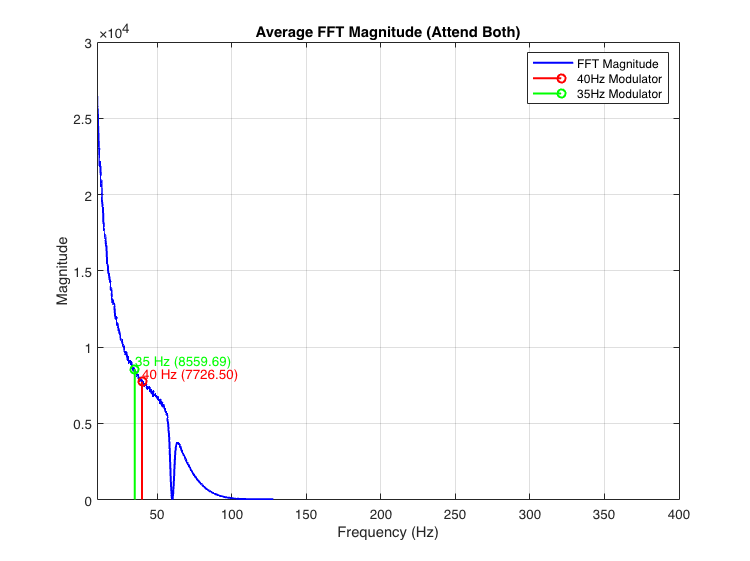

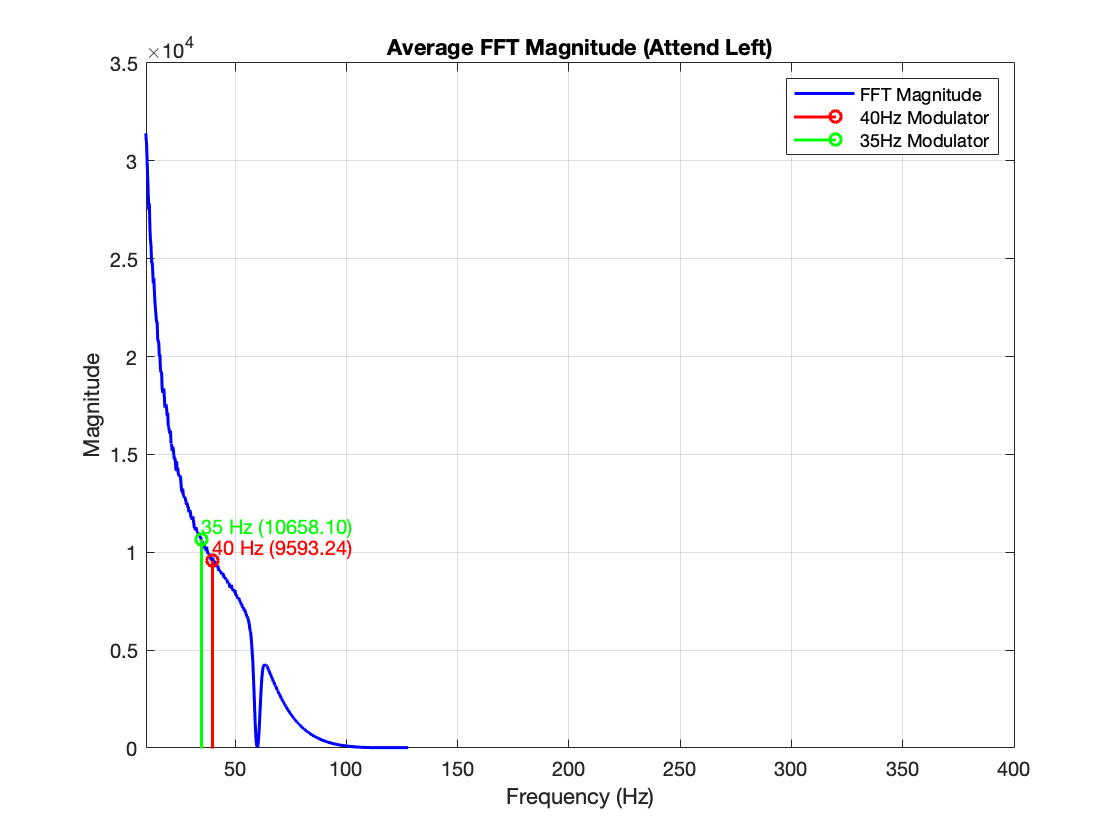

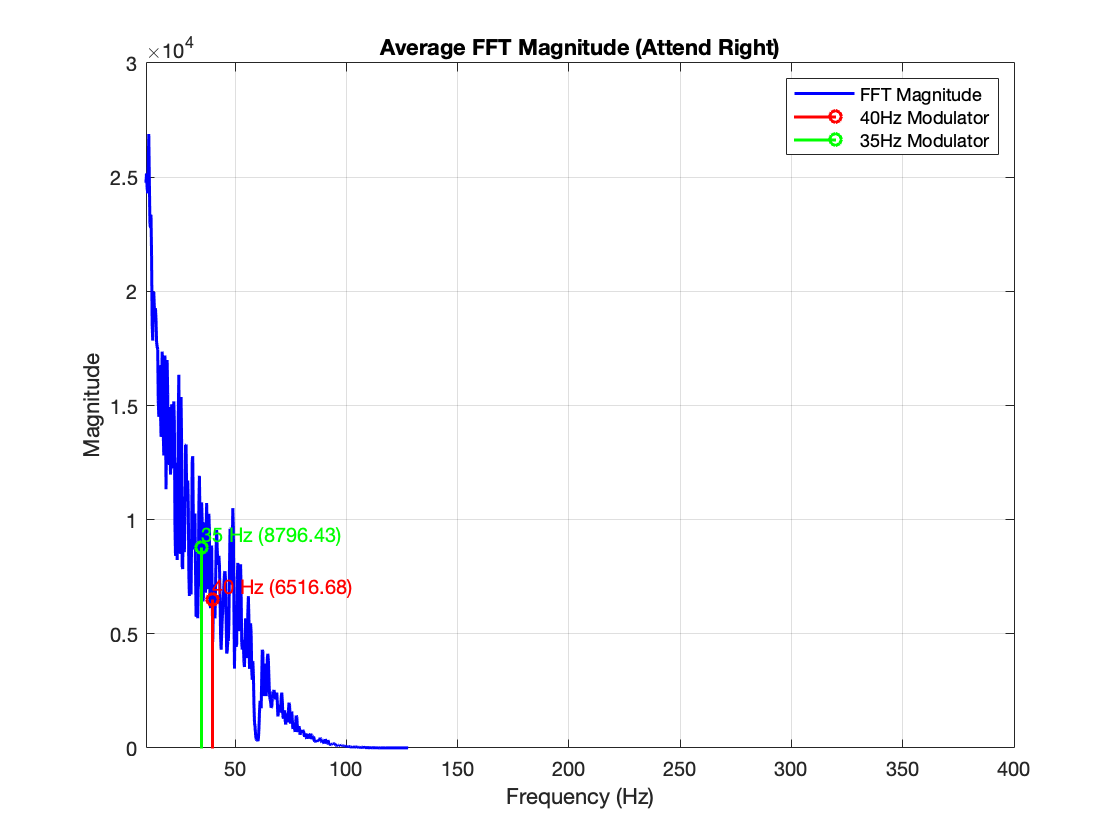

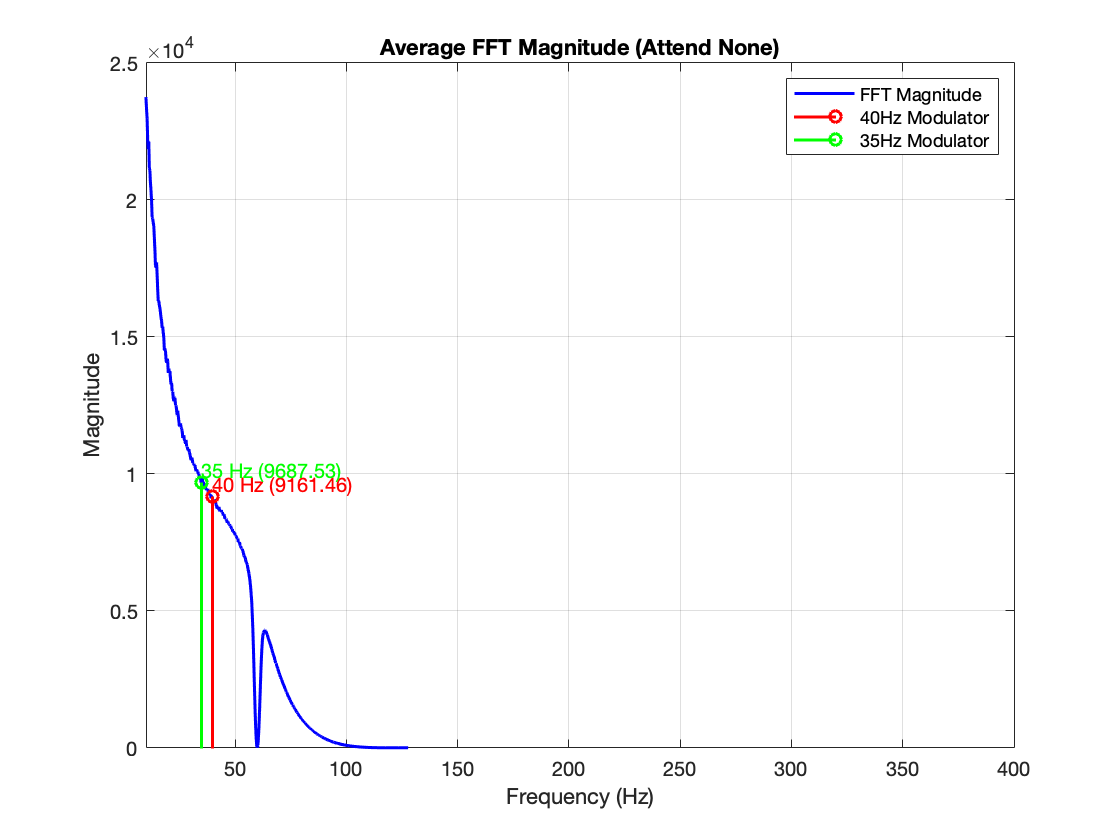

fprintf('FFT index for 35 Hz: %d, Corresponding Frequency: %.2f Hz\n', indices_35Hz, freq_vector(indices_35Hz));

## Question 5: Create a table or bar graph showing the average magnitude of the ASSR signal over all channels for the two modulator frequencies and for each of the four listening conditions. 

## How do you interpret the data? (6 pts)

- So based on just the average magnitudes, the 35Hz is higher for all 4 sessions. I think if we were going to predict on a threshold like in experiment 3, we shouldn't just predict based on the magnitude of one being bigger than the other. I think the difference between the magnitudes should be past a certain threshold and that may be more informative in this case. Especially because simply because the right ear may be dominant for the participant and it might be skewing the results.

- I also think in this case the attention modulation is weak. The expected effects of attention are not clearly reflected in the data. In the attend left condition, the 40 Hz response does not dominate, as one might expect if attention were effectively enhancing the left ear response.Similarly, in attend both, the responses do not converge or balance.

- Additionally we reccorded these sessions when it was very loud in lab so it is possible the attention to the sound was not optimal.

- It seems like we are seeing that when both or none are present they tend to balance each other out more which is expected.

- Overall I would have expected 25Hz to go down in attend left but there may have been experimental error or environmental distruptors,


fs = 256;
mod_frequencies = [40, 35]; 
nfft = 1024; 


conditions = {'Lab7_group5_p1_attend_both_mat', 'Lab7_group5_p1_attend_left_mat', ...
              'Lab7_group5_p1_attend_right_mat', 'Lab7_group5_p1_attend_none_mat'};
titles = {'Attend Both', 'Attend Left', 'Attend Right', 'Attend None'};


assr_magnitudes = zeros(length(conditions), length(mod_frequencies));

freq_vector = (0:(nfft/2 - 1)) * (fs / nfft); 

for cond_idx = 1:length(conditions)
    data_matrix = loadedData.(conditions{cond_idx}).ans;
    
    eeg_data = data_matrix(2:8, :);

    n_channels = size(eeg_data, 1);

    fft_magnitudes = zeros(n_channels, nfft / 2); % Preallocate for magnitude of FFT
    for ch = 1:n_channels
        %only positive frequencies
        fft_result = fft(eeg_data(ch, :), nfft); 
        fft_magnitudes(ch, :) = abs(fft_result(1:nfft/2)); %positive frequencies
    end

    %FFT magnitude over all channels
    avg_fft_magnitude = mean(fft_magnitudes, 1);

    %FFT magnitudes at the modulator frequencies
    for freq_idx = 1:length(mod_frequencies)
        mod_freq = mod_frequencies(freq_idx);
        mod_index = round(mod_freq * nfft / fs); 
        assr_magnitudes(cond_idx, freq_idx) = avg_fft_magnitude(mod_index); 
    end
end


conditions_column = titles'; 
assr_table = array2table(assr_magnitudes, 'RowNames', conditions_column, ...
                         'VariableNames', {'ASSR_40Hz', 'ASSR_35Hz'});


disp('Average ASSR Magnitudes for Each Condition and Frequency:');

Average ASSR Magnitudes for Each Condition and Frequency:


disp(assr_table);

                    ASSR_40Hz    ASSR_35Hz
                    _________    _________

    Attend Both      7726.5       8559.7  
    Attend Left      9593.2        10658  
    Attend Right     6516.7       8796.4  
    Attend None      9161.5       9687.5  



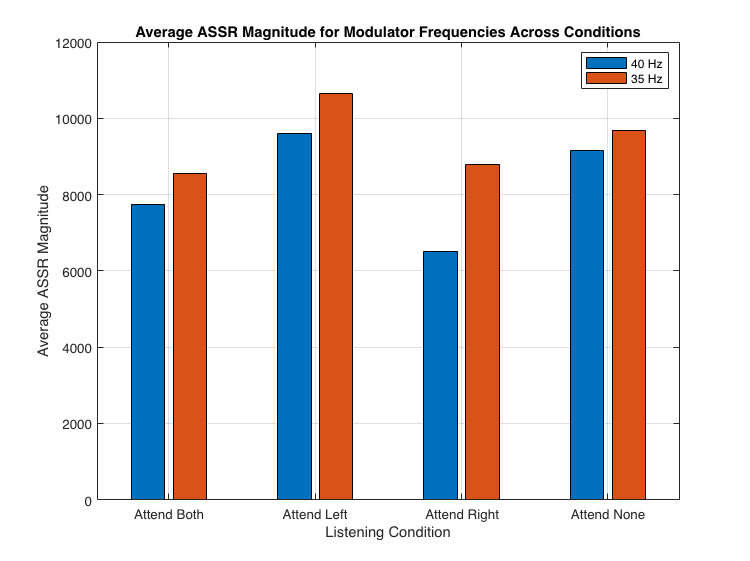



figure;
bar(assr_magnitudes);
xticks(1:length(conditions));
xticklabels(titles);
xlabel('Listening Condition');
ylabel('Average ASSR Magnitude');
legend({'40 Hz', '35 Hz'}, 'Location', 'NorthEast');
title('Average ASSR Magnitude for Modulator Frequencies Across Conditions');
grid on;